### Bisección.

Consideremos el punto 4 del Taller 01:

clear

% Definimos la función f con @(x)
f = @(x) exp(x) .* cos(3.*x) - sin(5.*x + 1)

f = function_handle with value:
    @(x)exp(x).*cos(3.*x)-sin(5.*x+1)


% Evaluemos los extremos
f([-2, 1.5])

ans =     0.5421   -1.7432


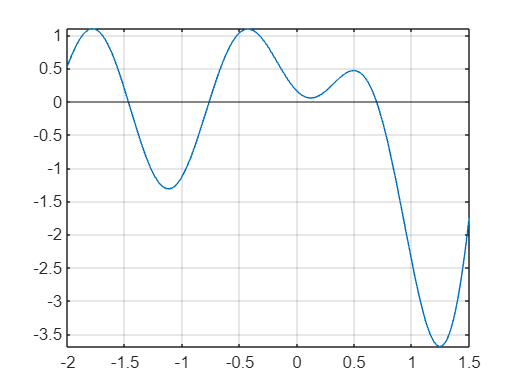

% Gráfiquemos la función
clf("reset")            % Reseteamos la figura
fplot(f, [-2, 1.5])     % Gráficamos en el intervalo
yline(0)                % Linea en y = 0
grid on                 % Activamos la malla

% Con el comando Help podemos visualizar la
% Documentación de nuestros métodos.
help bisect

  Entrada - f es la funcion introducida con @
 	      - a y b son los extremos izquierdo y derecho
 	      - delta es la tolerancia
  Salida  - c es el cero
 	      - yc = f(c)
  	      - err es el error estimado para  c



% Verifiquemos el uso del método
[c, ~, err] = bisect(f, -2, 1.5, 1e-15)

c = 0.6923

err = 1.4433e-15

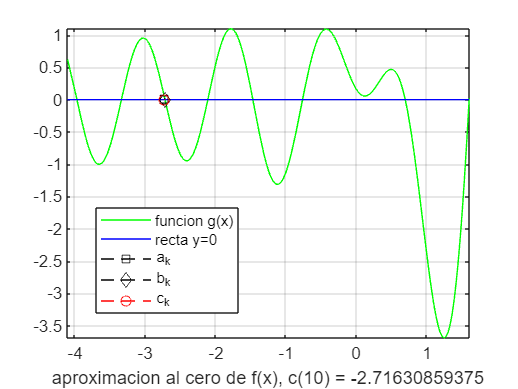

clf('reset')
animacionbisect(f, -4, 1.5, 1e-2);

### Punto Fijo.

Consideremos el punto 3 del Taller 02:

clear

% Definición de la función usando simbolos
syms g(x)
g(x) = -1 + 1/4 * (exp(x) - 2)^2

$$g(x) = \frac{{\left({\mathrm{e}}^{x}-2\right)}^{2}}{4}-1$$

% De simbolos podemos convertir a función estandar
g = matlabFunction(g)

g = function_handle with value:
    @(x)(exp(x)-2.0).^2./4.0-1.0


% Verifiquemos los argumentos de punto fijo
help fixpt

  Entrada - g funcion creada con @
          - p0 es el supuesto inicial para el punto fijo
          - tol es la tolerancia
          - max1 es el numero maximo de iteraciones
  Salida  - p es la aproximacion del punto fijo
 	      - k es el numero de iteraciones realizadas
 	      - err es el error en la aproximacion
 	      - P' contiene la secuencia {pn}

    Folders named fixpt



% Comprobemos el funcionamiento del método
[p, k, err] = fixpt(g, (-3 + 1)/2, 1e-15, 100)

p = -0.5102

k = 42

err = 5.5511e-16

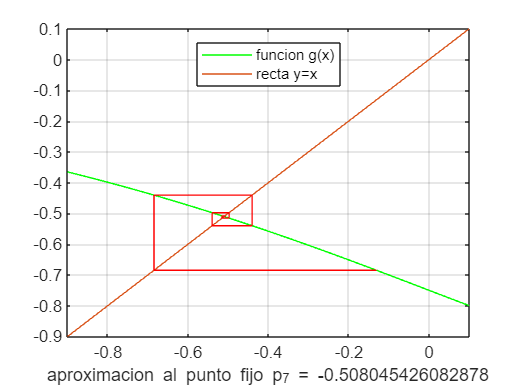

% Revisemos una animación del método
animacionfixpt(g, -2, 1e-2, 100);